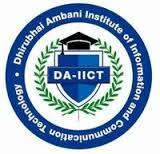

# CT216: Introduction to Communication Systems

# Lab 3: Random Variables and the Probability Distribution Functions

In this Lab 3 exercise, you will perform statistical experiments and obtain a hands-on understanding of the various type of probability distributions - both discrete and continuous. You will experiment with the additive white Gaussian noise (AWGN) model of the impairments affecting the communication channel. Most of the programs are already given to you as a part of this Matlab Live Editor and you will be experiementing with them.

The experiments you will be performing in this Lab are also called ``simulations''. This is an English word whose meaning, roughly, is ``recreating a real-world situation by modeling it in software (or sometimes even in hardware)''. You will perform what is called the Monte Carlo simulation.

The Monte-Carlo method is a numerical simulation method for statistical parameter evaluation. This was invented by Stanislaw Ulam. The following are his words (see also [this Wikepdia page.](https://en.wikipedia.org/wiki/Monte_Carlo_method))

*The first thoughts and attempts I made to practice [the Monte Carlo Method] were suggested by a question which occurred to me in 1946 as I was convalescing from an illness and playing solitaires. The question was what are the chances that a Canfield solitaire laid out with 52 cards will come out successfully? After spending a lot of time trying to estimate them by pure combinatorial calculations, I wondered whether a more practical method than ``abstract thinking'' might not be to lay it out say one hundred times and simply observe and count the number of successful plays. This was already possible to envisage with the beginning of the new era of fast computers, and I immediately thought of problems of neutron diffusion and other questions of mathematical physics, and more generally how to change processes described by certain differential equations into an equivalent form interpretable as a succession of random operations. Later [in 1946], I described the idea to John von Neumann, and we began to plan actual calculations.*

## Simulation of Discrete Random Variables (RVs)

### A Binary Information Source, i.e., the Bernouilli($q$) RV 

The output of any information-generating source can be modeled as the Bernoulli(q) RV provided the source output takes one of two values, i.e., the size of the source alphabet $K=2$ (e.g., toss of a coin, the status of bodily health for a particular disease, the birth of a girl or a boy, whether it snows/rains on a particular day at a particular location, etc.). Here, $q$ is the probability that the Bernoulli RV takes value of 1 (sometimes this $q$ is denoted as $p$ also; make sure the notation does not lead to a confusion), and this RV is characterized by its probability mass function or PMF, which is given as $p_X(x) = [1-q, q]$, where the first element of this array corresponds to the probability that $X= 0$ and the second element denotes the probability that $X= 1$. 

#### ***Step 1 Initialization***

Begin by setting up the simulation parameters:

Nsim = 776 % Set the number of Monte Carlo simulations

Nsim = 776

q = 0.63% control the value of q by moving the slider

q = 0.6300

#### ***Step 2 Generation of the RV***

Use Matlab's rand function to generate N instances of the Bernouilli RV $X$. This is as if you did a series of $N_{sim}$ experiments, where in each experiment you toss a coin. At the end you will have $N_{sim}$ results (the outcome of each toss). The Matlab does this series of experiements much faster and we can easily control the property of the coin (the parameter $q$, which is called its biased-ness, $q = 0.5$ denotes an unbiased coin since it does not favor the outcome $X = 0$ versus $X = 1$). Also as a side note and on lighter vein, a real-world coin can possibly land on its edge where it somehow manages to perfectly balance itself (this is if we trust what is shown in an iconic Hindi movie) such that the outcome of the toss is neither $0$ nor $1$. We do not consider such possibilities in the following one line of simulation. Note that this is a succinct simulation code in Matlab. Make sure that you understand what Matlab does within this one line. If you wish, you can write your own program to do what this one line of code below does.

X = rand(1,Nsim)<q; % this is a quick way to generate Nsim realizations of Bernouilli(q) RV X. Understand well what this one line of code does.

#### ***Step 3 Time Domain Visualization (TDV)***

This shows us how the entire series of experiements turned out as a (time-domain) sequence. 

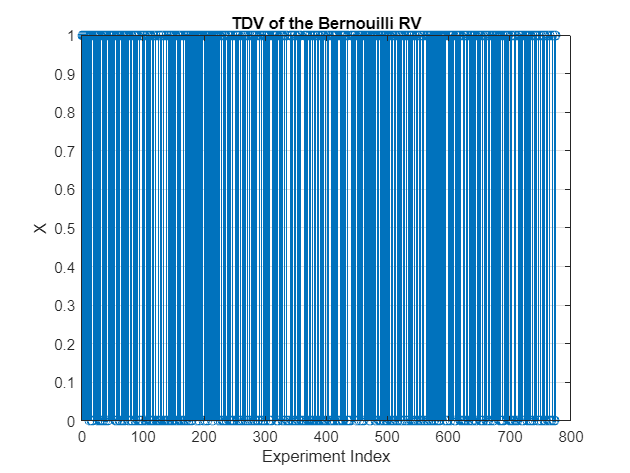

stem(1:Nsim,X(1:Nsim)); grid
xlabel('Experiment Index'); ylabel('X'); 
title('TDV of the Bernouilli RV')

#### ***Step 4 Statistical Evaluation***

In this part, we will confirm that the generated RV $X$ is indeed the Bernouilli RV with the specified parameter $q$. We will create two bins $X = 0$ and $X = 1$ and count the number of times $X$ falls in each bin. This is called the histogram evaluation by Monte Carlo method. The Matlab has an inbuilt function called histcounts that does this (if you feel motivated, you can write your own histogram calculator function in Matlab instead). You will observe that the simulated PMF is in agreement with the theoretical PMF (does this agreement improve or worsen if $N_{sim}$ is increased?).

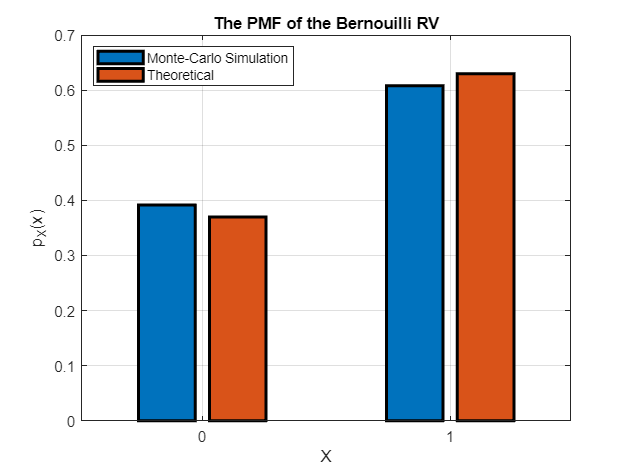

xBins = [0 1];
xEdges =[-0.5 0.5 1.5] ;
pmf_simulated = histcounts(X,xEdges)/Nsim;
pmf_theoretical = [1-q q];

bar(xBins,[pmf_simulated; pmf_theoretical]','linewidth',2); grid;
xlabel('X'); ylabel('p_X(x)'); title('The PMF of the Bernouilli RV');
legend('Monte-Carlo Simulation','Theoretical','location','northwest'); 

#### **Step 4 Continued, More Statistics**

Evaluate the mean and the variance of the simulated RV and compare them against the theoretical expressions. 

% the first element is the simulation result, the second is the theoretical value

xMeanSimulated_vs_theoretical = [mean(X) q] 

xMeanSimulated_vs_theoretical =     0.6082    0.6300



xVarianceSimulated_vs_theory = [var(X) q*(1-q)]

xVarianceSimulated_vs_theory =     0.2386    0.2331


### An $(N+1)$-ary Information Source: the Binomial$(q,N)$ RV  

[The Binomial RV](https://online.stat.psu.edu/stat414/lesson/10) $X$ is a non-binary but discrete-valued RV which finds many applications in the communication theory in specific and in many problems of the machine learning in general (there are, in fact, many real life problems that can be answered using the Binomial model).

This RV is defined as follows: $X = \sum_{n = 1}^N Z_n$, where each $Z_n$ , $1 \leq n \leq N$, is the Bernouilli($q$) RV. One important requirement is that these $N$ RVs which are summed to obtain $X$ have to be independent random variables for $X$ to be binomial. This independence assumption is maintained in the Monte Carlo simulations below. The Binomial RV is controlled by two parameters $q$ and $N$, which, as you may have noticed, are specified in its name. The RV itself takes one of $N+1$ values from the set $[0, 1, \ldots, N]$ (the first value occurs if all $N$ RVs $Z_n$ are zeros, the last value occurs if all of them are ones).

The PMF of this RV is given as $p_X(x=k) = {N\choose k} q^k (1-q)^{N-k}$ , where $0 \leq k \leq N$. Can you understand why this particular PMF formula is correct (why is the binomial coefficient multiplied with the powers of $q$ and $1-q$ in this specific way)? The expectation and variance of this RV are $Nq$ and $Nq(1-q)$. You will notice that there is a simple relation between these two expressions and the expressions of the mean and the variance of the Bernouilli RV.  

#### ***Step 2 Generation of the RV***

(make sure that you have executed Step 1 for the Bernouilli RV before you run this part of the program). There are multiple ways to generate the Binomial RV. One possibility is to run $N_{sim}$ trials, and generate and add $N$ Bernouilli RVs in each trial. This would require either a FOR or a WHILE loop. In Matlab, there is, however, a simpler way to do this, which avoids the looping (Matlab runs faster if you avoid the FOR or WHILE loops). Here, we generate a matrix of size $N \times N_{sim}$ whose elements are the Bernouilli RVs, and then we sum each column of this matrix. This will give us $N_{sim}$ realizations of the Binomial RV. You should try alternative (e.g., FOR loop based) method of generating the Binomial RV. Matlab also provides an inbuilt function called [Binornd](https://de.mathworks.com/help/stats/binornd.html). Once you know how to generate this RV yourself, you can directly use Matlab's inbuilt function.

N = 6;
Z = rand(N,Nsim)<q;
X = sum(Z); % Matlab sum function takes a sum of each column of the input matrix

#### ***Step 3 Time Domain Visualization (TDV)***

This shows us how the entire series of experiements turns out as a (time-domain) sequence. 

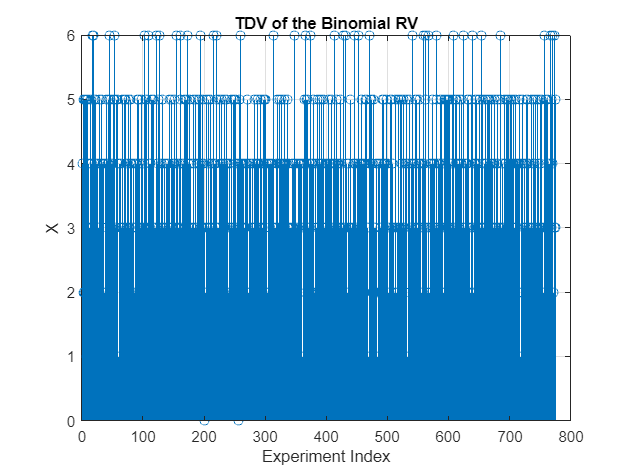

stem(1:Nsim,X(1:Nsim)); grid
xlabel('Experiment Index'); ylabel('X'); 
title('TDV of the Binomial RV')

#### ***Step 4 Statistical Evaluation***

In this part, we will confirm that the generated RV $X$ is indeed the Binomial RV. We will create $N+1$ bins from $X = 0, 1, \ldots,$ to $X = N$ and count the number of times $X$ occurs in each bin. You will observe that the simulated PMF is in agreement with the theoretical PMF, which is obtained using Matlab's inbuilt binopdf function. You can consider writing your own function that calculates the Binomial PMF.

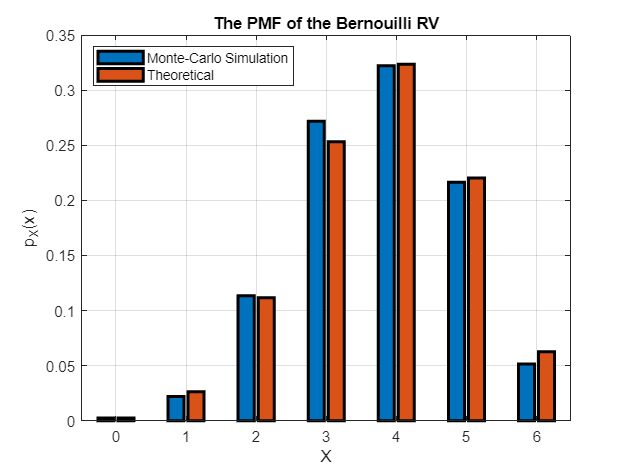

xBins = 0:N;
xEdges =[-0.5 xBins+0.5]; % understand why the edges of the histogram bins have to be defined in this manner

pmf_simulated = histcounts(X,xEdges)/Nsim;

pmf_theoretical = binopdf(xBins,N,q);

bar(xBins,[pmf_simulated; pmf_theoretical]','linewidth',2); grid;
xlabel('X'); ylabel('p_X(x)'); title('The PMF of the Bernouilli RV');
legend('Monte-Carlo Simulation','Theoretical','location','northwest'); 

#### **Step 4 Continued, More Statistics**

Evaluate the mean and the variance of the simulated RV and compare them against the theoretical expressions. 

% the first element is the simulation result, the second is the theoretical value

xMeanSimulated_vs_theoretical = [mean(X) N*q] 

xMeanSimulated_vs_theoretical =     3.7448    3.7800



xVarianceSimulated_vs_theory = [var(X) N*q*(1-q)]

xVarianceSimulated_vs_theory =     1.3232    1.3986


## Simulation of Continuous Random Variables (RVs)  

In this part, we will be studying the continuous RVs. These take analog values (i.e., the source alphabet is the entire real number line and its size is infinity) in contrast with the discrete RVs which take one value from a finite sized set. The [PDF is a continuous-valued counterpart of the PMF](https://online.stat.psu.edu/stat414/lesson/14/14.1). 

### Uniform Distribution

The [Uniform Probability Distribution Function](https://online.stat.psu.edu/stat414/lesson/14/14.6) is used to model a Continuous (or Analog-valued) Random Variable (RV) $X$ that takes values over a range $[a, b]$ with a probability density function or PDF $p_X(x) = 1/(b-a)$. An application of this distribution is in analyzing the effect of quantization noise that arises when the analog samples of a Discrete-Time (D-T) signals are quantized. 

The expected or the mean value of this RV is given as $m_X = E[X] = \int_{x = a}^b x p_X(x) dX$. A simple integration will show to you that the mean of the uniform PDF is given as $(a+b)/2$. The variance of this RV, given as $Var[X] = E[X^2] - (m_X)^2$ is given as $(b-a)^2/12$. You should be able to derive this formula yourself, or you can see the derivation on [Penn State Statistics Department](https://online.stat.psu.edu/stat414/lesson/14/14.6) website. 

#### Step 1 Initialization

Begin by setting up the simulation parameters:

a = 0; b = 2; % change these values and observe the effect

#### Step 2 Modeling of the Source Output

Use Matlab's rand function to generate $N_{sim}$ instances of the uniform RV $X$, which is uniformly distributed over the specified range $[a, b]$.

X = a + (b-a)*rand(1,Nsim); % understand what this line of code does

#### Step 3 Time Domain Visualization (TDV)

See how the uniform random variable looks like if a sequence of them occurs one after another in the time.

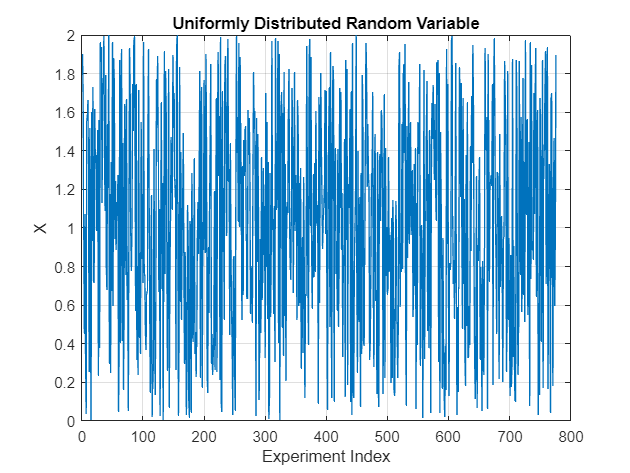

plot(1:Nsim,X(1:Nsim)); grid
xlabel('Experiment Index'); ylabel('X'); 
title('Uniformly Distributed Random Variable')

#### Step 4 Statistical Characterization

In this part, you will confirm that the generated RV $X$ is indeed uniformly distributed. You will create multiple bins, specifically $(b-a)/stepsize$ number of bins in the range $[a, b]$ for the Monte Carlo histogram evaluation. You will observe that the frequency with which $X$ falls in any one bin is roughly the same as it falls in any other bin. As before, observe how well does the simulated PDF pdf_simulated compare against the theoretically-evaluated uniform PDF. 

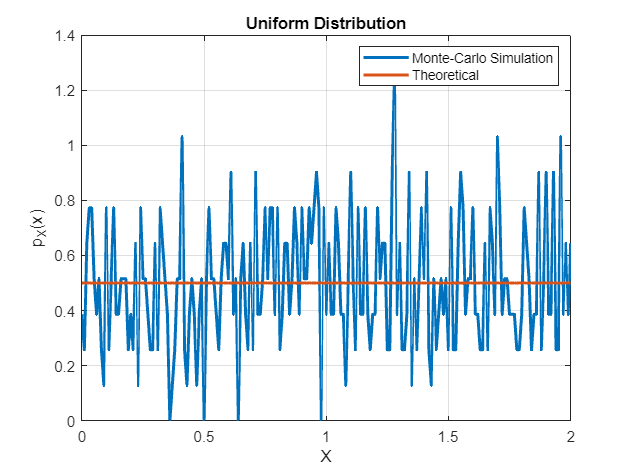

stepsize = 0.01; 
xBins = a:stepsize:b;
xEdges = [a-stepsize/2 xBins+stepsize/2];

pdf_simulated = histcounts(X,xEdges)/stepsize/Nsim;

% Use Matlab's unifpdf function to generate the 
% analytical (mathematical formula based) PDF.

% do a help search to know about Matlab's unifpdf function

pdf_theoretical = unifpdf(xBins,a,b);

plot(xBins,[pdf_simulated; pdf_theoretical],'linewidth',2); grid
xlabel('X'); ylabel('p_X(x)'); title('Uniform Distribution');
legend('Monte-Carlo Simulation','Theoretical');

#### Step 5 Statisics Continued

Evaluate the mean and the variance of the simulated RV and compare them against the theoretical expressions.

xMeanSimulated_vs_theoretical = [mean(X) (a+b)/2] 

xMeanSimulated_vs_theoretical =     1.0225    1.0000



xVarianceSimulated_vs_theory = [var(X) (b-a)^2/12]

xVarianceSimulated_vs_theory =     0.3280    0.3333


### The Gaussian RV 

The last PDF we will study in this Lab is the Gaussian PDF. [The Gaussian Distribution](https://en.wikipedia.org/wiki/Normal_distribution) arises in many real-life scenarios, and it is famous (and known even to a layman) for its bell shape. 

In the communication systems, the Gaussian PDF (also known as the Normal PDF and denoted as $N(\mu, \sigma)$, where $\mu$ is the mean and $\sigma$ is the standard deviation) arises in modeling the probability distribution of the additive noise that affects the transmitted signal.

Repeat the above experiment for the Gaussian distributed Random Variables (RVs). Following changes are needed to the program listing given above. 

#### Steps 1 and 2 Initialization and Source Output Generation

The Gaussian distributed random variables $N(\mu, \sigma)$ can be generated (or simulated) as follows: 

muGauss = 1; varGauss = 1; stdGauss = sqrt(varGauss); 
X = stdGauss*randn(1,Nsim)+muGauss;

#### Step 3 TDV

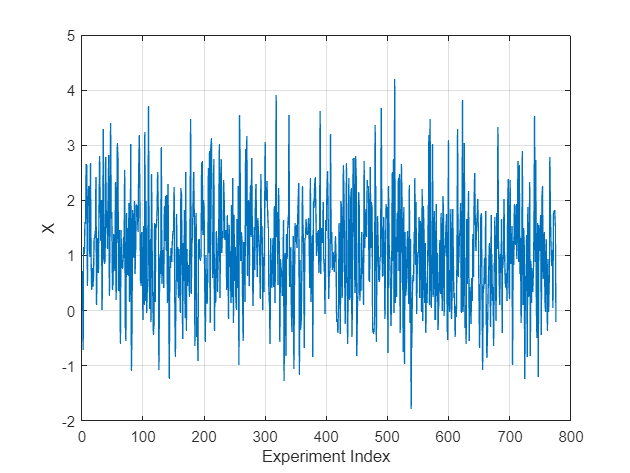

% add code to do the TDV
plot(1:Nsim,X(1:Nsim)); grid
xlabel('Experiment Index'); ylabel('X');

#### Steps 4 and 5 Statistical Characterization

Evaluate the simulated PDF in the same manner as for the Uniform RV, except generate xBins based on the limits (or the end-points) of the generated variable. 

stepsize = 0.01; 
xBins = [muGauss-4*stdGauss:stepsize:muGauss+4*stdGauss];
xEdges = [xBins(1)-stepsize/2 xBins+stepsize/2];

Add your code below to compute the simulated PDF.

% add your code here
pdf_simulated = histcounts(X,xEdges)/stepsize/Nsim;

Use Matlab’s normpdf function to generate the analytical (mathematical formula based) PDF (do a help search to know about Matlab’s normpdf function). 

pdf_theoretical = normpdf(xBins,muGauss,stdGauss); 

Compare the results of your Monte-Carlo simulation against the theoretical results. Do this comparison for the PDF, its mean and the variance.

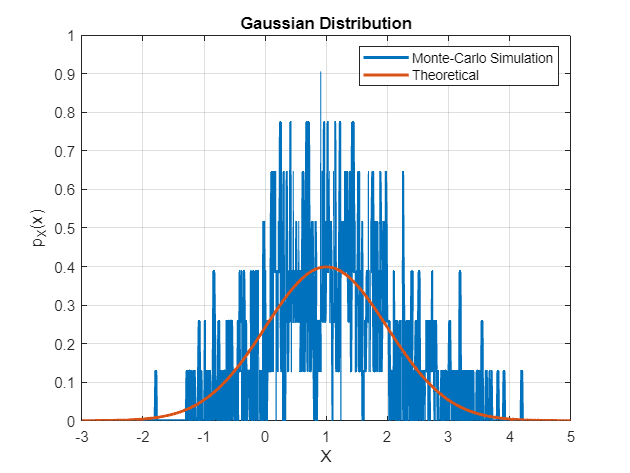

% add your code here
plot(xBins,[pdf_simulated; pdf_theoretical],'linewidth',2); grid
xlabel('X'); ylabel('p_X(x)'); title('Gaussian Distribution');
legend('Monte-Carlo Simulation','Theoretical');

% Matlab Question 1

% Rakshit Pandhi 202201426

% Defining all the variables needed

alpha=0:0.01:1;

Pn=1; % Noise to be taken 1
P1rx= 1;% assumed to be 1 (can take any values)

P2rx_0db=10.^(0/10)* P1rx;
P2rx_6dB = 10.^(6/10) * P1rx; % Received power for user 2 (6 dB difference)
P2rx_12dB = 10.^(12/10) * P1rx; % Received power for user 2 (12 dB difference)

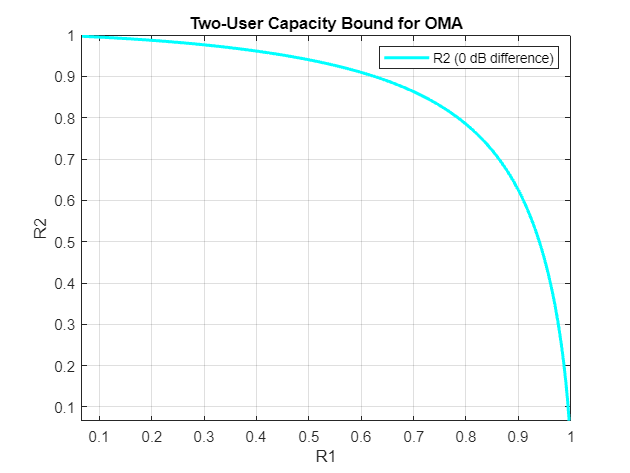

% Calculating capacity bound for 0dB case
R1 = alpha .* log2(1 + P1rx ./ (alpha * Pn));
R2_case_0dB= (1-alpha) .* log2(1+P2rx_0db ./ ((1-alpha)* Pn));

color=[0.4660, 0.6740, 0.1880];
figure;
plot(R1, R2_case_0dB, 'cyan', 'LineWidth', 2);

xlabel('R1');
ylabel('R2');
xlim([min(R1), max(R1)]);
ylim([min(R2_case_0dB),max(R2_case_0dB)]);
title('Two-User Capacity Bound for OMA');
legend('R2 (0 dB difference)');
grid on;

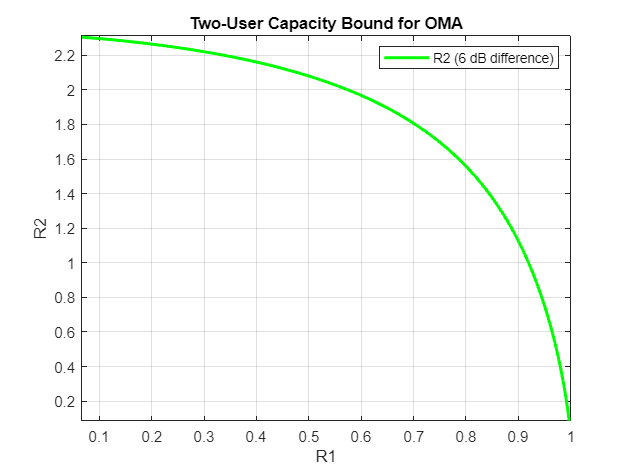

% Calculating capacity bound for 6dB case
R1 = alpha .* log2(1 + P1rx ./ (alpha * Pn));
R2_case_6dB = (1 - alpha) .* log2(1 + P2rx_6dB ./ ((1 - alpha) * Pn));

plot(R1, R2_case_6dB, 'g', 'LineWidth', 2);
xlabel('R1');
ylabel('R2');
xlim([min(R1), max(R1)]);
ylim([min(R2_case_6dB),max(R2_case_6dB)]);
title('Two-User Capacity Bound for OMA');
legend('R2 (6 dB difference)');
grid on;

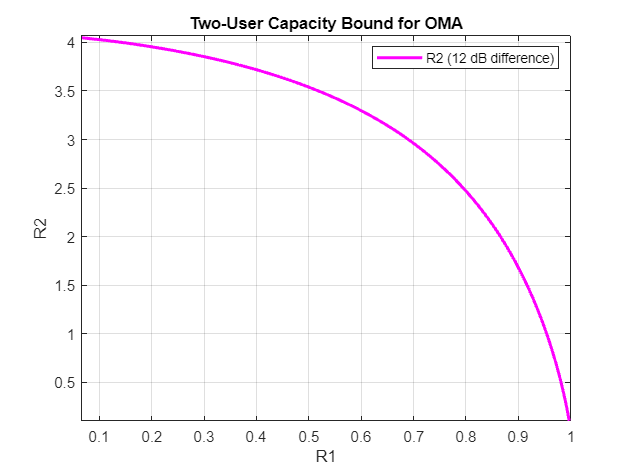

% Calculating capacity bound for 12dB case
R1 = alpha .* log2(1 + P1rx ./ (alpha * Pn));
R2_case_12dB = (1 - alpha) .* log2(1 + P2rx_12dB ./ ((1 - alpha) * Pn));

plot(R1, R2_case_12dB, 'magenta', 'LineWidth', 2);
xlabel('R1');
ylabel('R2');
xlim([min(R1), max(R1)]);
ylim([min(R2_case_12dB),max(R2_case_12dB)]);
title('Two-User Capacity Bound for OMA');
legend('R2 (12 dB difference)');
grid on;